## **Tool  zur Erstellung von technischen Graphen**

In diesem Matlab-File sind verschiedene Vorlagen fuer unterschiedliche Graphen. Dieses Tool soll die Erstellung von Prakikumsberichten vereinfachen. 

(c) Malte Mueller 2019

## Einfacher X-Y-Plot

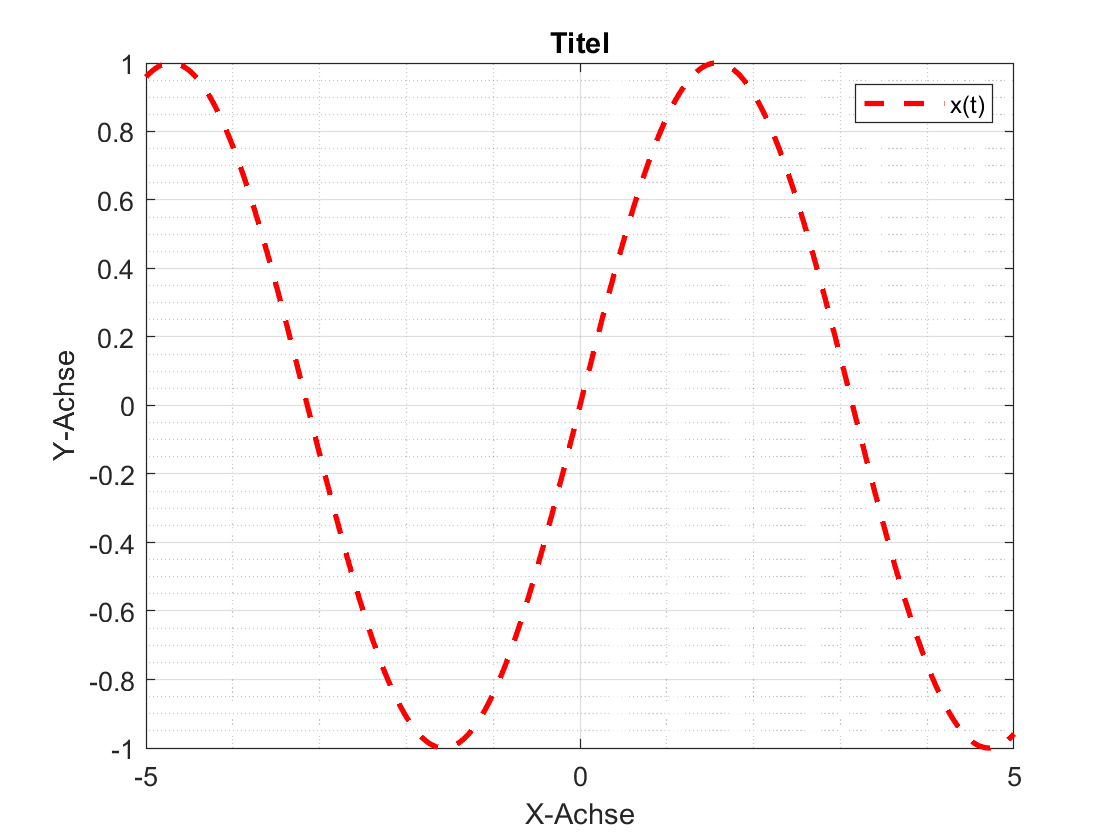

t = -5:0.01:5;
x = sin(t);

plot(t,x, 'r--', 'LineWidth', 2);

% Farben:
% 'b = blue (default)', 'k = black', 'r = red', 'g = green', 
% 'y = yellow', 'c = cyan', 'm = magenta'

% Datenpunkte:
% '-', '--', 'o', '+' , 'x', '*'

grid on; grid minor;

title("Titel");
xlabel("X-Achse"); ylabel("Y-Achse");
legend("x(t)");

## STEM-Plot

Darstellung Fourierkoeffizienten, ..

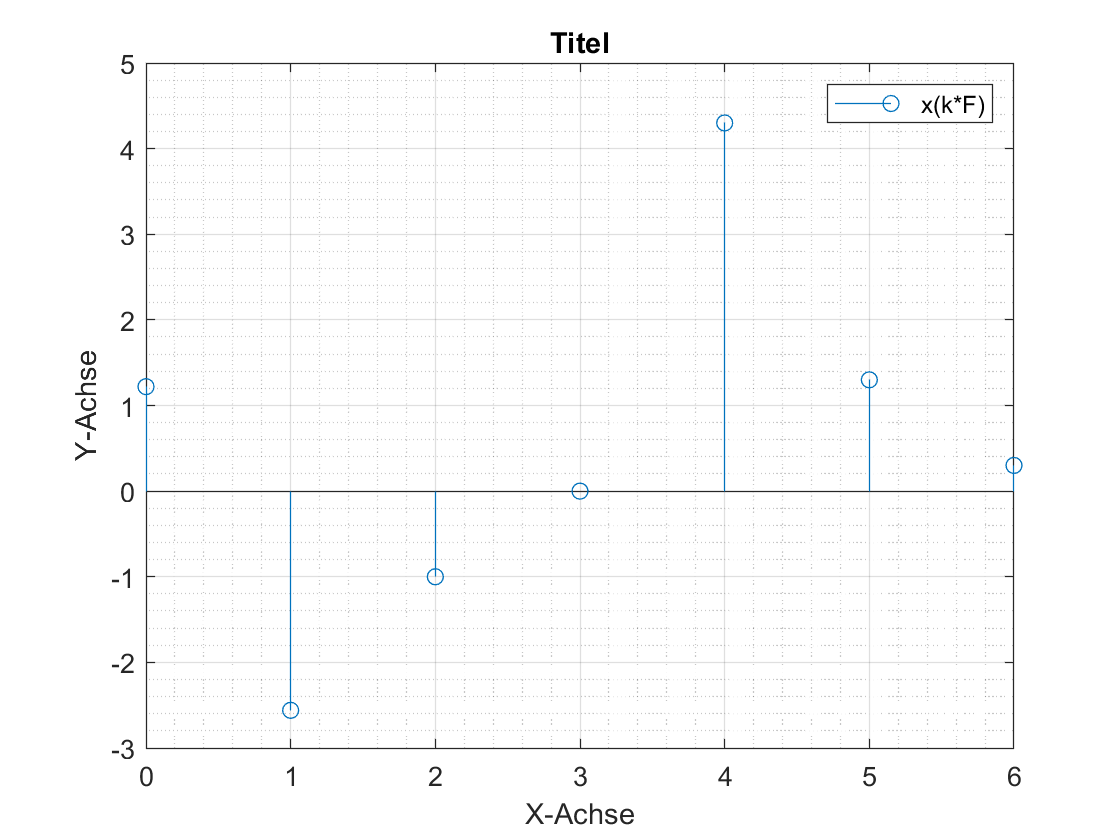

k = 0:1:6;
x = [1.22, -2.56 , -1 , 0, 4.3, 1.3, 0.3];

stem(k, x);

grid on; grid minor;

title("Titel");
xlabel("X-Achse"); ylabel("Y-Achse");
legend("x(k*F)");

## Mehrere X-Y-Plots in einen Graphen

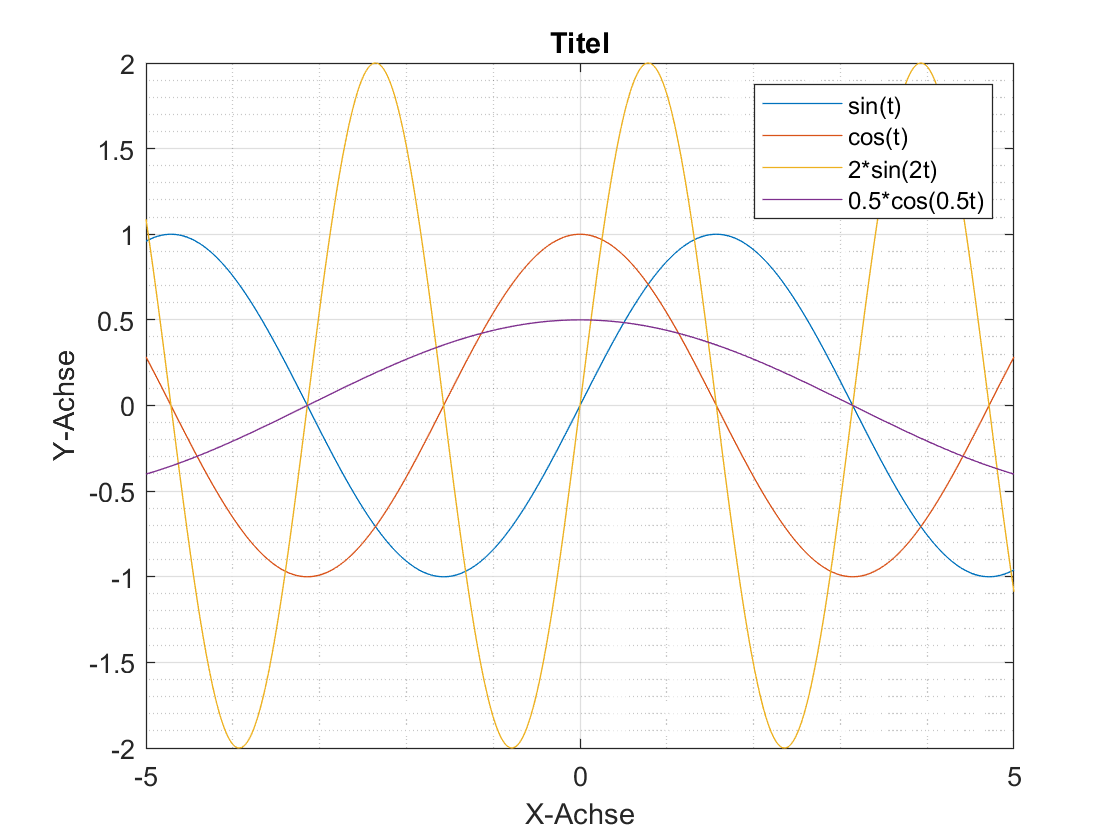

t = -5:0.01:5;

plot(t, sin(t), t, cos(t), t, 2*sin(2*t), t, 0.5*cos(0.5*t));

grid on; grid minor;

title("Titel");
xlabel("X-Achse"); ylabel("Y-Achse");
legend("sin(t)", "cos(t)", "2*sin(2t)", "0.5*cos(0.5t)");

## Mehrere X-Y-Plots zeitversetzt in einen Graphen

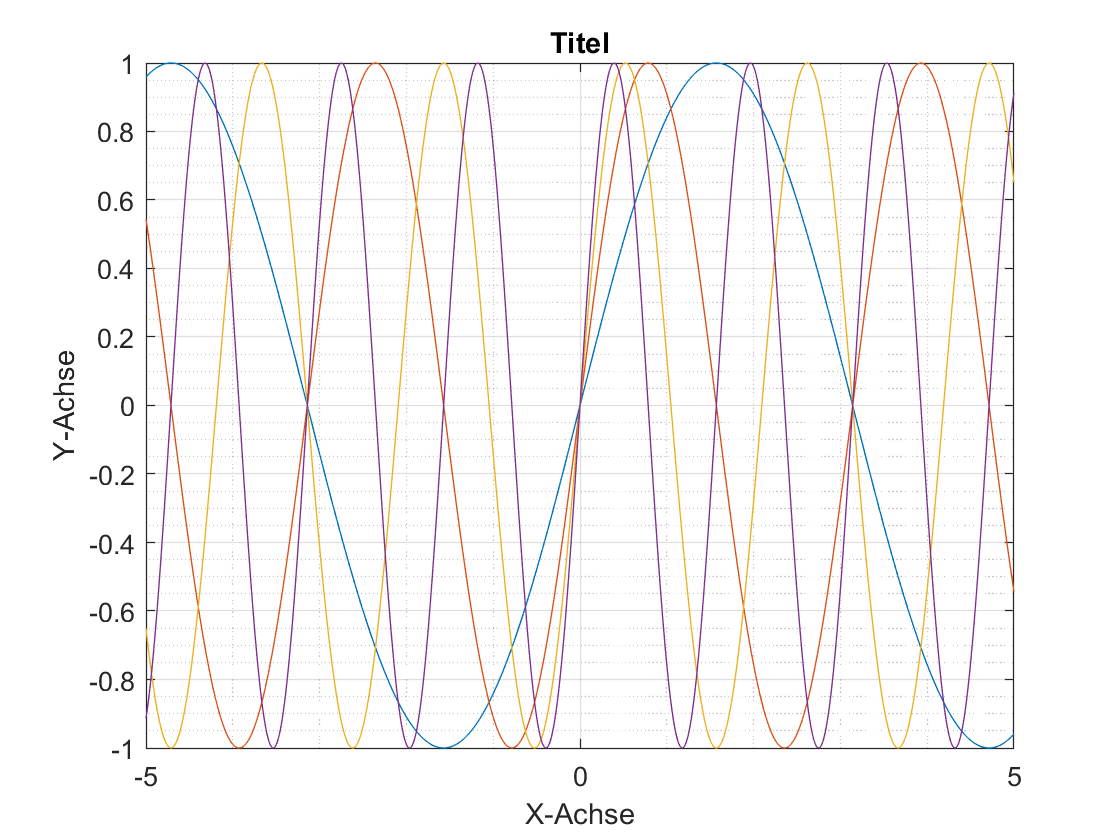

t = -5:0.01:5;

for k = 1:4
    plot(t, sin(k*t));
    hold on;
end

grid on; grid minor;
title("Titel");
xlabel("X-Achse"); ylabel("Y-Achse");

hold off;

## 3D-Graphen

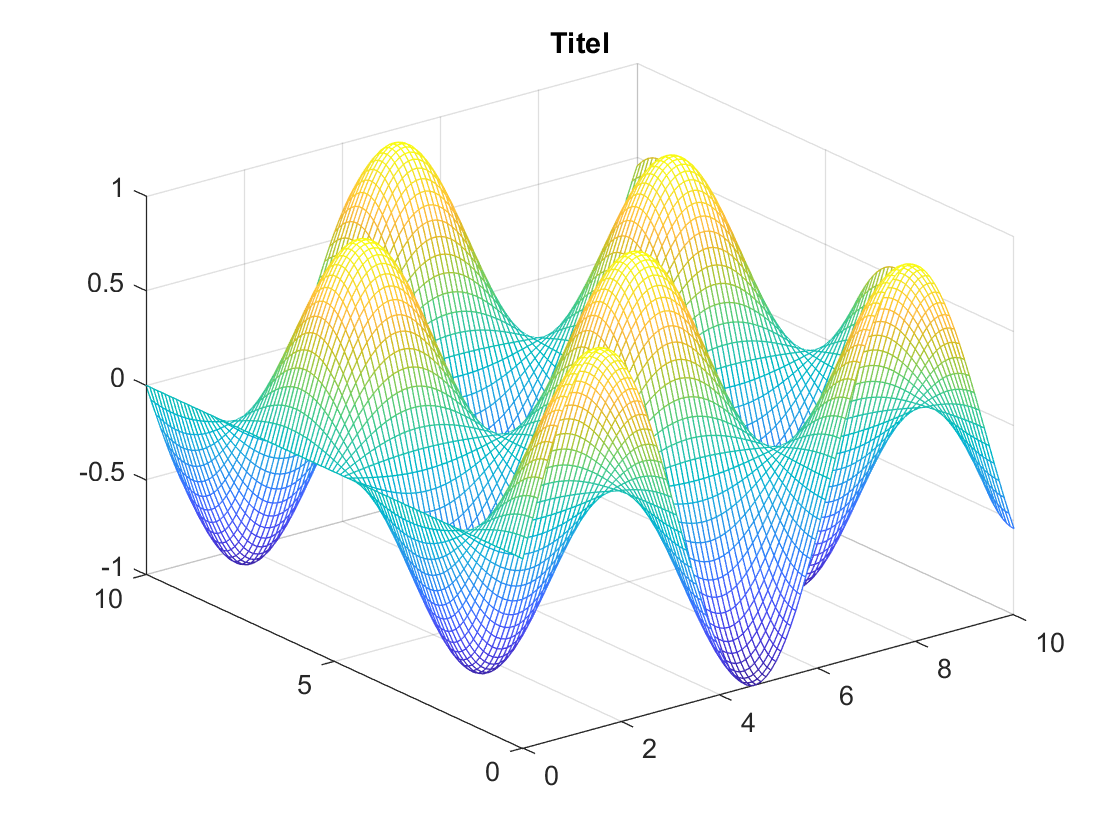

[x,y]=meshgrid(linspace(0,10));

z=sin(x).*cos(y);
mesh(x,y,z)
title('Titel')

## 2 Subplots untereinander

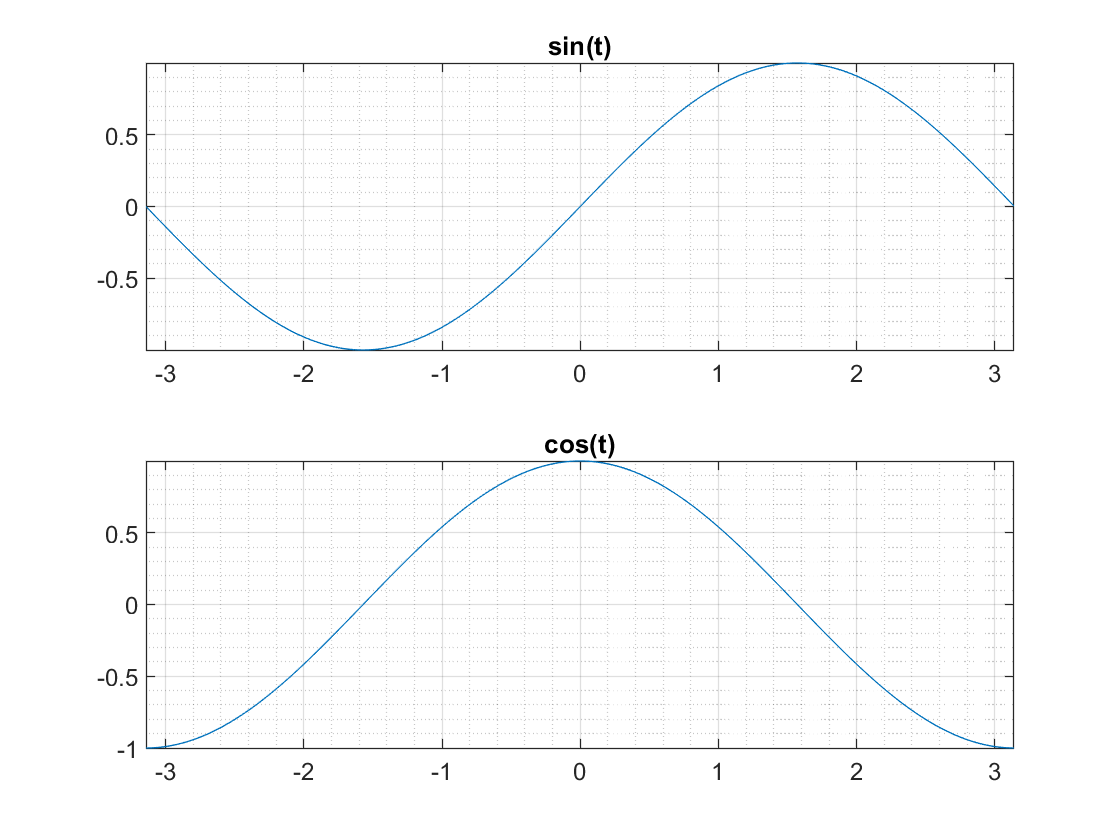

t = -pi:0.01:pi;

ax1 = subplot(2,1,1);
    plot(t, sin(t)); grid on; grid minor; axis tight;
    title("sin(t)");
ax2 = subplot(2,1,2);
    plot(t, cos(t)); grid on; grid minor; axis tight;
    title("cos(t)");

## 2 Subplots nebeneinander

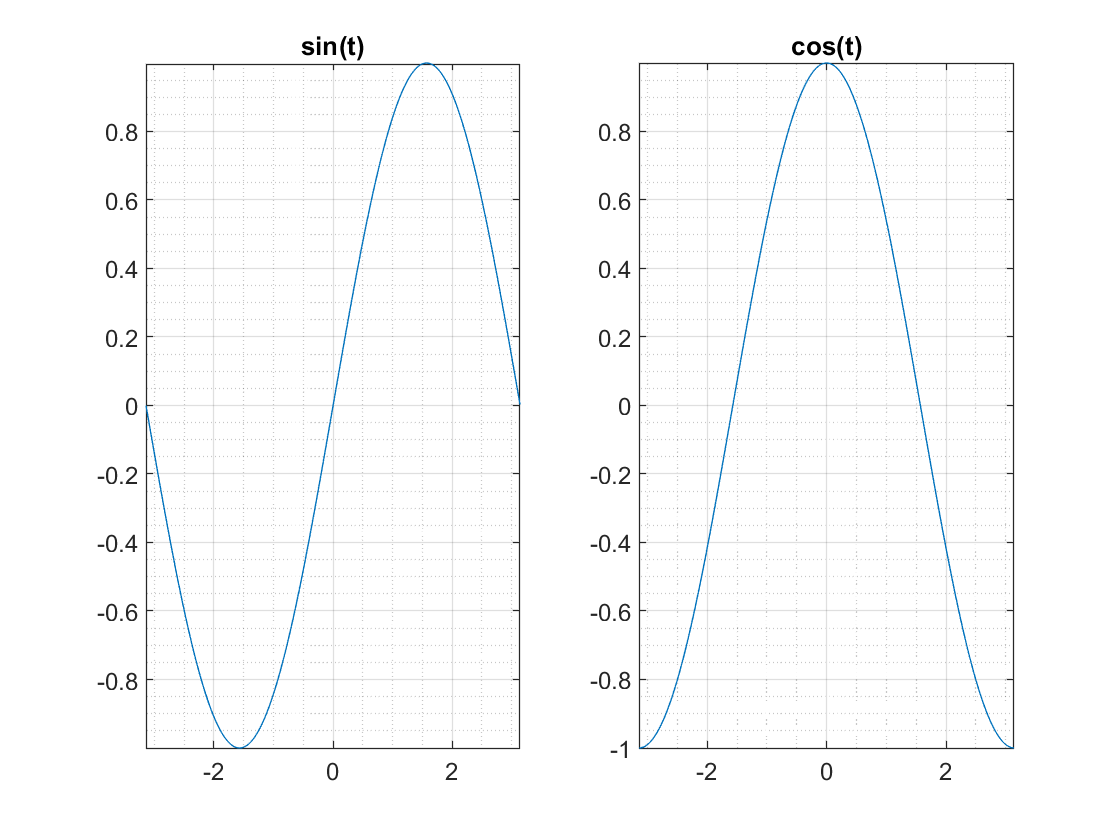

t = -pi:0.01:pi;

ax1 = subplot(1,2,1);
    plot(t, sin(t)); grid on; grid minor; axis tight;
    title("sin(t)");
ax2 = subplot(1,2,2);
    plot(t, cos(t)); grid on; grid minor; axis tight;
    title("cos(t)");

## 4 Subplots

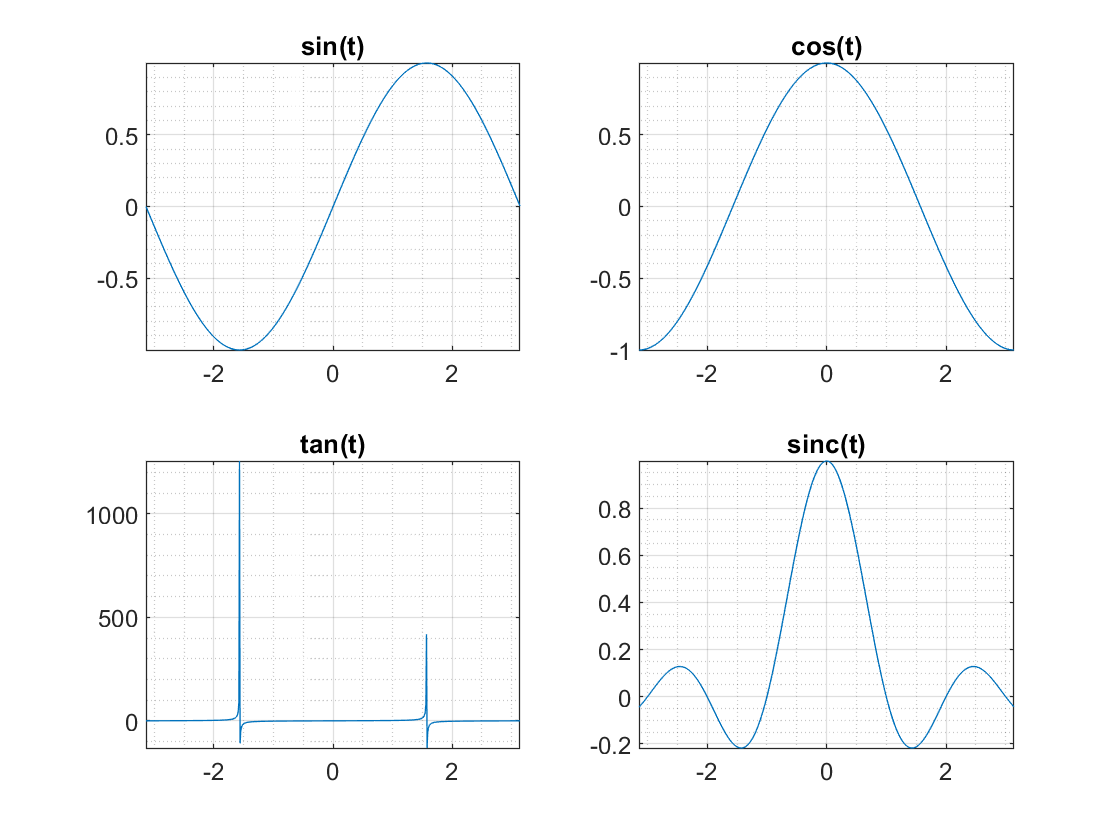

t = -pi:0.01:pi;

ax1 = subplot(2,2,1);
    plot(t, sin(t)); grid on; grid minor; axis tight;
    title("sin(t)");
ax2 = subplot(2,2,2);
    plot(t, cos(t)); grid on; grid minor; axis tight;
    title("cos(t)");
ax3 = subplot(2,2,3);
    plot(t, tan(t)); grid on; grid minor; axis tight;
    title("tan(t)");
ax4 = subplot(2,2,4);
    plot(t, sinc(t)); grid on; grid minor; axis tight;
    title("sinc(t)");